# Aula 6 - Laboratório de Controle - 2021/1

## Métodos de sintonia dos ganhos do controlador PID

## Nome: Yuri Rissi Negri

I=8 ; 
turma=5 ;
W=[4 8 2 11 5 3 12 9 1 6 7 10;9 7 2 8 4 12 6 3 5 10 11 1;
     6 12 9 8 10 7 2 4 1 3 5 11;10 11 7 3 1 2 8 12 5 9 6 4;1 10 5 3 11 7 9 12 4 8 2 6]';
g=tf(0.9*I^4,poly(-[1 1 1 1]*I));

## Atividade 1 - Obtenção de modelos de ordem 1

Os comandos abaixo geram 13 modelos de ordem 1 para diferentes atrasos. Analise os gráficos gerados nas figura 1 e 2 e responda as perguntas 1.1 a 1.3.

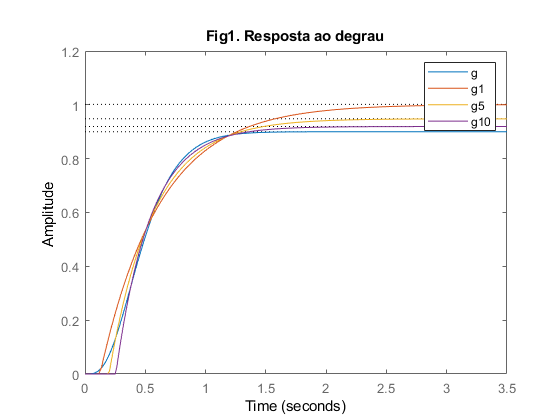

[delay, tau, K, fit, Kp]=funcao_g1(g);
g1=tf(K(1),[tau(1) 1],'InputDelay', delay(1));
g5=tf(K(5),[tau(5) 1],'InputDelay', delay(5));
g10=tf(K(10),[tau(10) 1],'InputDelay', delay(10));
figure;
step(g,g1,g5,g10);legend('g','g1','g5','g10');title('Fig1. Resposta ao degrau');

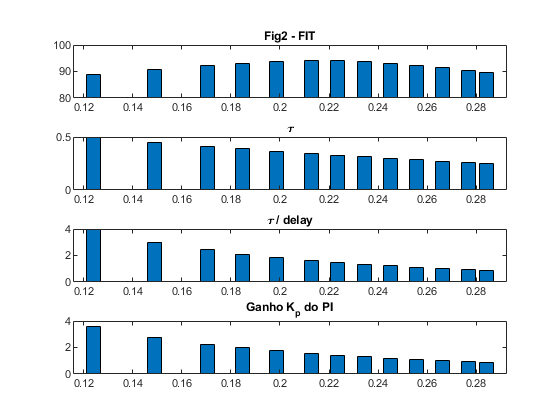


figure;
subplot(4,1,1);bar(delay,fit);title('Fig2 - FIT');ylim([80 100])
subplot(4,1,2);bar(delay,tau);title('\tau'); 
subplot(4,1,3);bar(delay,tau./delay);title('\tau / delay'); 
subplot(4,1,4);bar(delay,Kp);title('Ganho K_p do PI')

A Tabela 1 mostra como são calculados os ganhos dos controladores P, PI ou PID usando o método de Ziegler-Nichols 

usando um modelo de primeira ordem definido por $G(s)=\frac{Ke^{-\theta}}{\tau s + 1}$. Dica:$K_i=1/T_{i}$ e $K_d=T_d$.

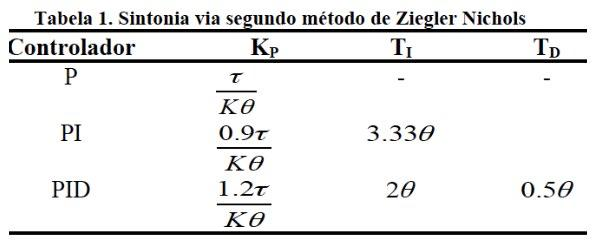

1.1 Que valor de delay dá o maior fit? Qual o fit?

    A curva de primeira ordem que apresenta o maior fit, ou seja, a curva que mais se aproxima da curva de g de ordem quatro, é a g6 que apresenta um tempo de delay de aproximadamente 0,213 segundos. Essa curva nos gera um fit de 94,03% de acordo com a figura 2. 

1.2 Explique o comportamento da relação tau/delay usando as figuras 1 e 2.

    Da figura 1, podemos ver que conforme aumentamos o delay, também temos um aumento do tempo morto (tempo em que a curva permanece em zero). Dessa forma como as curvas atingem 63% em pontos próximos, conforme aumentamos o tempo morto vamos diminuir a nossa constante de tempo. Podemos observar essa relação na figura 2, o que faz com que a relação tau/delay tenha uma relação inversa ainda maior com o aumento do delay, pois conforme aumentamos o delay vamos ter um menor valor de tau no numerador e um maior valor de delay no denominador.

1.3 Use a Tabela 1 para explicar o efeito de tau/delay sobre o ganho Kp do controlador (ver fig 2)

    Da tabela 1 do método de Ziegler-Nichols, podemos perceber que com a diminuição no termo tau/delay vamos ter um menor valor de Kp no nosso controlador. O efeito pode ser comprovado na figura 2, onde com o aumento do delay (e consequentemente diminuição de tau/delay) podemos observar menores valores para Kp.

## Atividade 2 - Efeito da relação tau/delay na sintonia do controlador

Nesta atividade são avaliados os 13 modelos gerados na atividade 1 para o projeto de um controlador PI via método  ZN (Tabela 1). 

A escolha do modelo é baseada em seu fit e também na boa resposta ao degrau obtida para  o controlador resultante (Ver Fig.3 ). Observe que o controlador 

é sempre testado na FT original g, e não no modelo usado para o projeto.

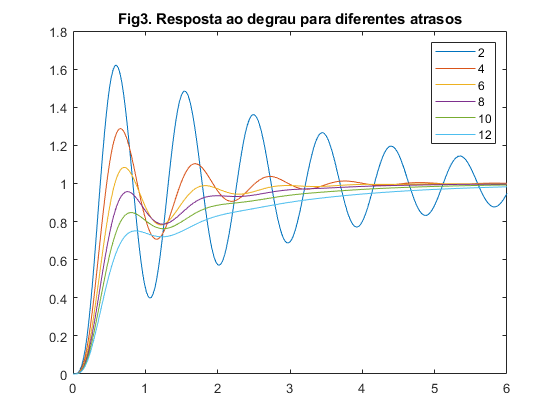

Tempo=6  ; 
t=linspace(0,Tempo,250);
Y=[];
for i=1:13
    g1=tf(K(i),[tau(i) 1],'InputDelay', delay(i));
    c1=sintonia(g1,'PI', 'zie');
    m1=feedback(c1*g,1);
    
    y=step(m1,t);
    Y=[Y y];
    Iae(i) = iaeupts(m1,t);
end;

figure;
plot(t,Y(:,[2 4 6 8 10 12]));
legend('2','4','6','8','10','12');
title('Fig3. Resposta ao degrau para diferentes atrasos')

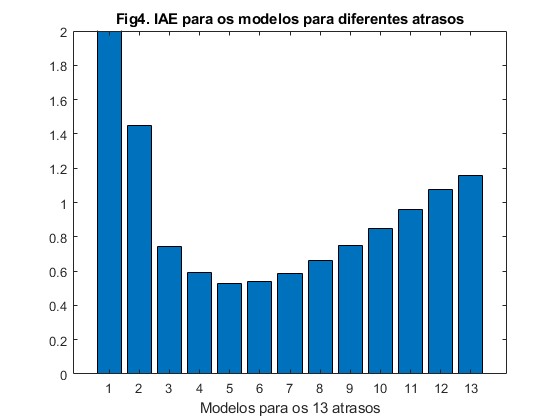


figure;
bar(Iae); ylim([0 2])
title('Fig4. IAE para os modelos para diferentes atrasos')
xlabel('Modelos para os 13 atrasos')

2.1 Qual o efeito de tau/delay no tempo de subida e sobreelevação? (Ver Kp na figura 2 e efeito na Figura 3)    

   Levando em conta que podemos associar o efeito de tau/delay com a valor de Kp, podemos observar que na figura 3 que a diminuição desses parâmetros gera uma menor sobreelevaçãoo no nosso sinal, como visto no laboratório anterior a relação direta da sobreelevação com Kp. Contudo, também podemos perceber que temos um sistema mais lento para menores valores de Kp, onde podemos reparar que tanto o tempo de subida como o de estabelecimento em geral tem um aumento conforme a relação tau/delay diminui.  

2.2 Baseado no IAE, qual o modelo mais adequado a ser utilizado e por quê? 

    Analisando a figura 4 a curva que apresenta o melhor IAE é a curva 5 (g5). Temos essa relação pelo mesmo motivo visto nos laboratórios anteriores, sendo a curva que mais se aproxima da nossa entrada unitária (apresenta a menor integral de erro). Analisando os valores de fit na figura 2, podemos perceber que em geral os valores mais desejados do IAE também são os melhores valores de fit. Assim, vamos escolher a curva 5 para a próxima atividade (i=5).

## Atividade 3 - Escolha do método de sintonia que dá o melhor controlador PI

Escolha o modelo g1 que será usado daqui para diante, usando as figuras das atividades 1 e 2, e definindo i na próxima linha. Este modelo será usado para projetar o controlador usando 4 métodos de sintonia.

## IMPORTANTE: Para avançar mostre ao professor o resultado das atividades 1 e 2 

## e justifique sua decisão pelo modelo a ser usado

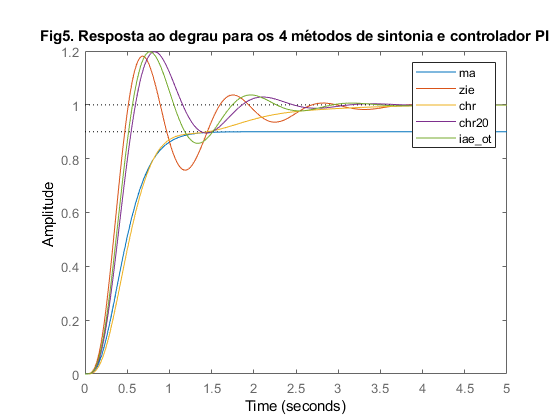

i=5; 
g1=tf(K(i),[tau(i) 1],'InputDelay', delay(i));
c1=sintonia(g1,'PI', 'zie');
c2=sintonia(g1,'PI', 'chr');
c3=sintonia(g1,'PI', 'chr20');
c4=sintonia(g1,'PI', 'iae_ot');

m1=feedback(c1*g,1);
m2=feedback(c2*g,1);
m3=feedback(c3*g,1);
m4=feedback(c4*g,1);

figure
Tempo=5; 
t=linspace(0,Tempo,250); 
step(g,m1,m2,m3,m4,Tempo);title('Fig5. Resposta ao degrau para os 4 métodos de sintonia e controlador PI');
legend('ma','zie','chr','chr20','iae_ot')

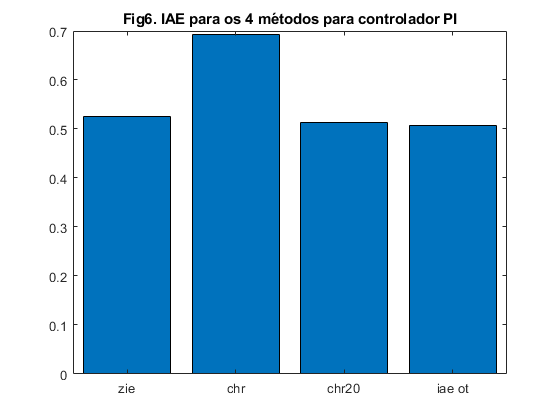

iae_pi=[iaeupts(m1,t) iaeupts(m2,t) iaeupts(m3,t) iaeupts(m4,t)];

leg1 = categorical({'zie','chr','chr20','iae ot'});
leg2 = reordercats(leg1,{'zie','chr','chr20','iae ot'});
figure;
bar(leg2,iae_pi);title('Fig6. IAE para os 4 métodos para controlador PI'); 
set(gca,'xticklabel',{'zie','chr','chr20','iae ot'});

3.1 Compare o IAE obtido pelos diferentes métodos e explique o motivo de valores altos de IAE observando a resposta ao degrau na figura 5

    Para o nosso sistema, podemos perceber ao analisar a figura 6 que o método que nos gerou um maior valor do IAE foi o "chr", dessa forma menos desejável. O motivo pode ser observado ao analisarmos a figura 5, sendo o método que nos deu a resposta mais lenta, com o maior tempo de subida, até mesmo em relação a nossa resposta em malha aberta. Sendo assim, o método mais desejável para o nosso sistema seria o "iae ot" que nos gerou o menor valor de IAE. 

## Atividade 4 - Escolha do método que dá o melhor controlador PID

Agora o controlador PID é selecionado para os 4 projetos.

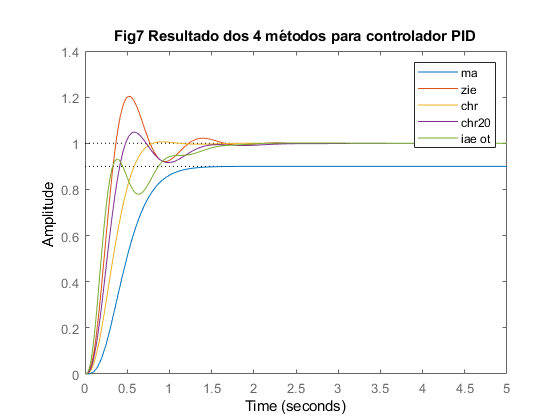

c1=sintonia(g1,'PID', 'zie');
c2=sintonia(g1,'PID', 'chr');
c3=sintonia(g1,'PID', 'chr20');
c4=sintonia(g1,'PID', 'iae_ot');

m1=feedback(c1*g,1);
m2=feedback(c2*g,1);
m3=feedback(c3*g,1);
m4=feedback(c4*g,1);

iae_pid=[iaeupts(m1,t) iaeupts(m2,t) iaeupts(m3,t) iaeupts(m4,t)];

figure
step(g,m1,m2,m3,m4,Tempo);
title('Fig7 Resultado dos 4 métodos para controlador PID');
legend('ma','zie','chr','chr20','iae ot')

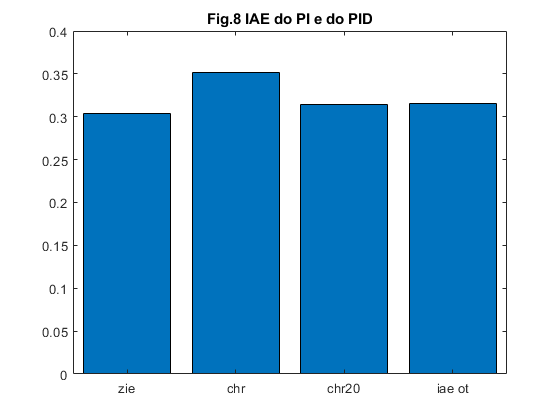


leg1 = categorical({'zie','chr','chr20','iae ot'});
leg2 = reordercats(leg1,{'zie','chr','chr20','iae ot'});

figure;
bar(leg2,iae_pid);
title('Fig.8 IAE do PI e do PID');

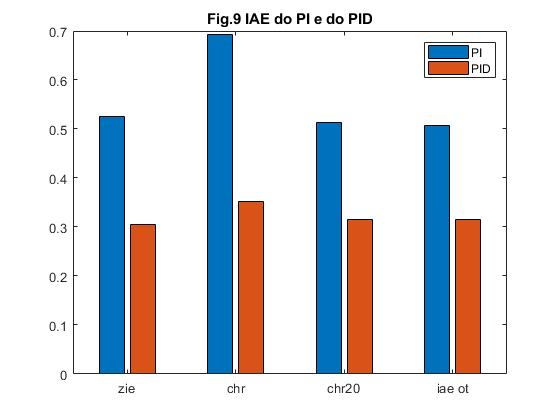



figure;
bar(leg2,[iae_pi; iae_pid]');
legend('PI','PID');title('Fig.9 IAE do PI e do PID');

4.1 Compare os valores de IAE do PID (Fig 8) obtido pelos diferentes métodos e explique o motivo de valores altos de IAE observando a resposta ao degrau na figura 7

    Para o controlador PID percebemos que existe uma menor diferença entre os valores de IAE entre os métodos. O maior valor de IAE continua sendo gerado no método "chr", ainda podemos perceber ao analisar a figura 7 que por esse método geramos uma resposta mais lenta em relação aos outros o que tem um grande impacto no calculo de IAE. Contudo, podemos perceber de maneira geral analisando o gráfico que a inserção de um Ki e um Kd no nosso sistema gerou respostas com menores valores de IAE. Já em relação ao método mais desejável basta observar qual obteve menor valor, que para o PID foi o "zie".

4.2 Compare o desempenho dos controladores PI e PID (Fig.9) em termos dos valores de IAE para os 4 métodos, usando as figuras de resposta ao degrau para justificar

   Podemos perceber que com a inserção de um controlador PID, todos os métodos tiveram uma melhor aproximação com menor valor de IAE em relação ao controlador PI do mesmo método. Mesmo o método "chr" que como visto anteriormente teve o maior valor de tempo de subida e maior IAE se aproximou do desempenho gerado pelos outros métodos. Vale ressaltar também que quando analisamos os métodos para um controle PID aquele que apresentou menor valor de IAE agora foi o método "zie" (Ziegler-Nichols) em contraste com o método "iae ot" que havia sido o melhor método para um controlador PI. Podemos observar também, quando comparamos as figuras 5 e 7, podemos perceber um tempo de estabelecimento menor no controlador PID em relação ao controlador PI, o que gera menores valores de IAE. 

## Atividade 5 - Avaliação da sintonia lambda com controlador PID

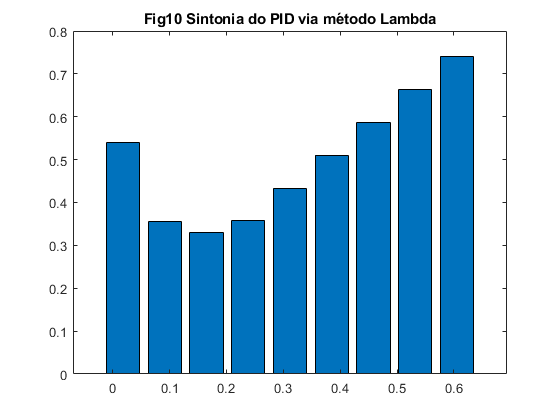

tau=g1.Denominator{1}(1);
lambda=tau*[0.05 0.25 0.45 0.65 0.85 1.05 1.25 1.45 1.65];
for i=1:length(lambda)
    c=sintonia(g1,'PID', 'lam',lambda(i));
    m=feedback(c*g,1);
    iael(i)=iaeupts(m,t);
end

figure
bar(lambda,iael);title('Fig10 Sintonia do PID via método Lambda');

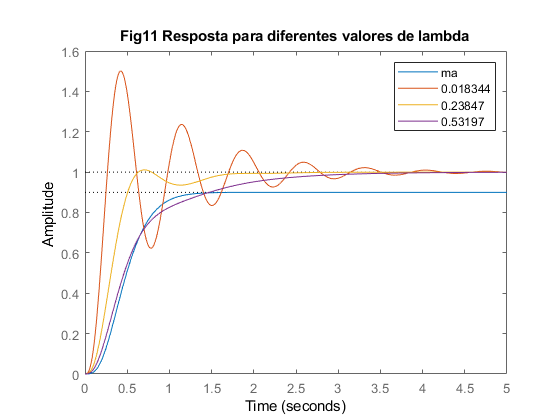


c1=sintonia(g1,'PID', 'lam',lambda(1));
c2=sintonia(g1,'PID', 'lam',lambda(4));
c3=sintonia(g1,'PID', 'lam',lambda(8));

m1=feedback(c1*g,1);
m2=feedback(c2*g,1);
m3=feedback(c3*g,1);

figure
step(g,m1,m2,m3,Tempo);title('Fig11 Resposta para diferentes valores de lambda')
legend('ma',num2str(lambda(1)),num2str(lambda(4)),num2str(lambda(8)))

5.1 Compare o desempenho dos controladores PID variando lambda com os controladores obtidos pelos outros métodos e justifique o resultado. Que valor de lambda deu menor IAE? Compare com o IAE ótimo e explique como obter o menor IAE com o método lambda.

   Analisando a figura 10, temos que o controlador PID para diferentes valores de lamba obteu o resultado mais desejável com menor valor de IAE = 0,3302 quando lamda era igual a 0,1651. Comparando com os outros controladores, os métodos anteriores tiveram um melhor resultado, com exceção do controlador "chr". Isso se deu pelo fato de que para o nosso sistema, a resposta do método lambda fica com uma menor sobreelevação mas com um maior tempo de subida que o método "zie" por exemplo. Assim podemos dizer que com o aumento de lambda temos um aumento no tempo de subida e que esse efeito é predominante no cálculo de IAE.

    Para se obter um menor IAE, devemos escolher menores valores de lambda mas que respeitem a condição de lambda/delay > 0,8. Assim podemos analisar a faixa de valores próximos a essa condição para determinar o melhor lambda, como feito para gerar a figura 10.

5.2 Qual o efeito na resposta em malha fechada de pequenos valores de lambda na sintonia do controlador? Por que?

    Quando selecionamos pequenos valores de lambda, vamos estar gerando grandes valores de Kp no controlador, o que traz consigo todas as resultantes de se aumentar Kp no sistema (aumento de sobreelevação e respostas mais rápidas). Fica fácil de se perceber isso ao analisarmos a figura 11. Conforme aumentamos os valores de lambda, atenuamos o efeito de Kp no sistema, gerando curvas mais lentas e com menor sobressinal. Isso se da pelo fato de que ao analisarmos a tabela de sintonia para a escolha de lambda, podemos perceber que para o calculo de Kp, o mesmo se encontra no denominador, sendo inversamente proporcionais. 

datetime('now')

ans = datetime
   23-Jul-2021 20:01:32


pwd

ans = 'C:\Users\asus1\Desktop\Aula6'